# CP8318 Project

## Create Data Labels

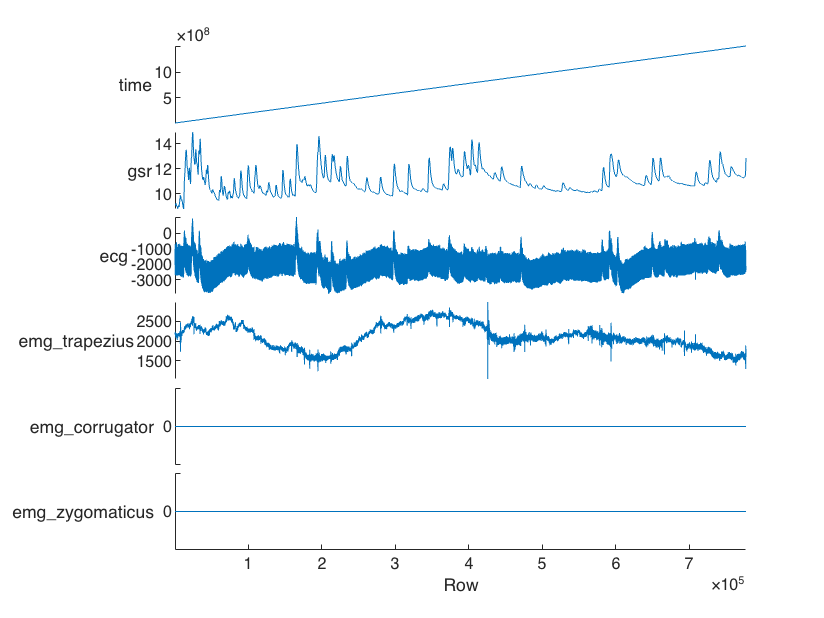

%load the new raw biosignal file
signal = readtable("071309_w_21_biosignal.csv");
figure
stackedplot(signal)

%load the label file
lbl = readBiovid("071309_w_21_label.csv");

lbl = 48569×2 table
       time       label
    __________    _____

         27500      0  
         58750      0  
         90000      0  
    1.2125e+05      0  
     1.525e+05      0  
    1.8375e+05      0  
      2.15e+05      0  
    2.4625e+05      0  
     2.775e+05      0  
    3.0875e+05      0  
       3.4e+05      0  
    3.7125e+05      0  
     4.025e+05      0  
    4.3375e+05      0  
      4.65e+05      0  
    4.9625e+05      0  


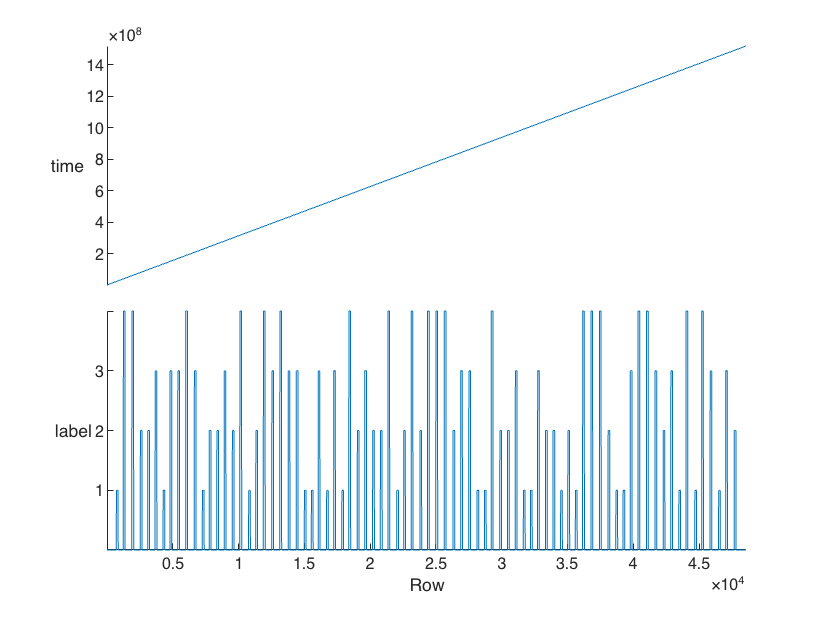

figure
stackedplot(lbl)

X = diff(lbl.label);
T = [];
for i = 1:size(X)
    if X(i)~= 0
        T = [T; i];
    end
end
T

T =          718
         847
        1248
        1377
        1899
        2028
        2539
        2668
        3106
        3235


%extract label for each time interval
label_L = [];
label_T = [];
for j = 1:size(T)-1
    label_L(end+1, :)= lbl.label(T(j+1));
    label_T(end+1, :)= lbl.time(j+1);
end
label_L

label_L =      1
     0
     4
     0
     4
     0
     2
     0
     2
     0


label_T

label_T =        58750
       90000
      121250
      152500
      183750
      215000
      246250
      277500
      308750
      340000


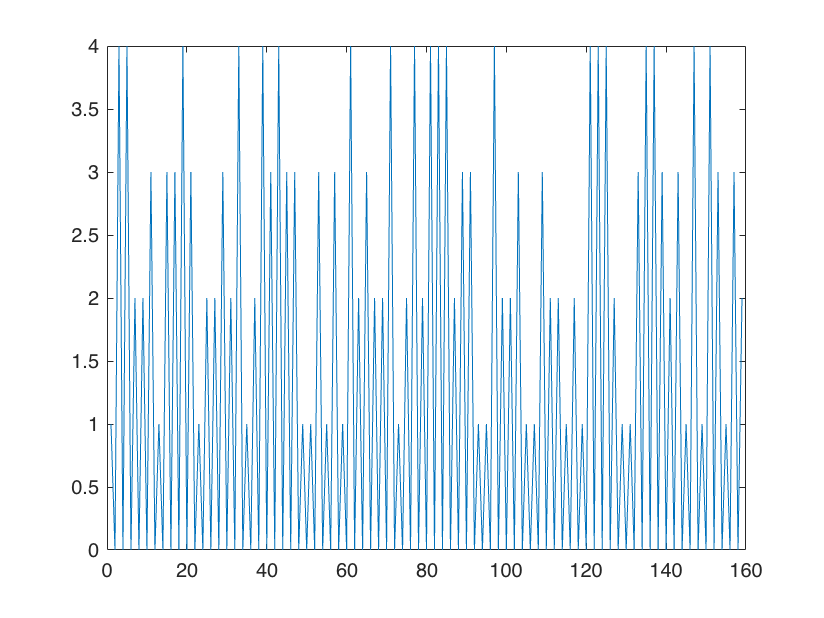

figure
plot(label_L)

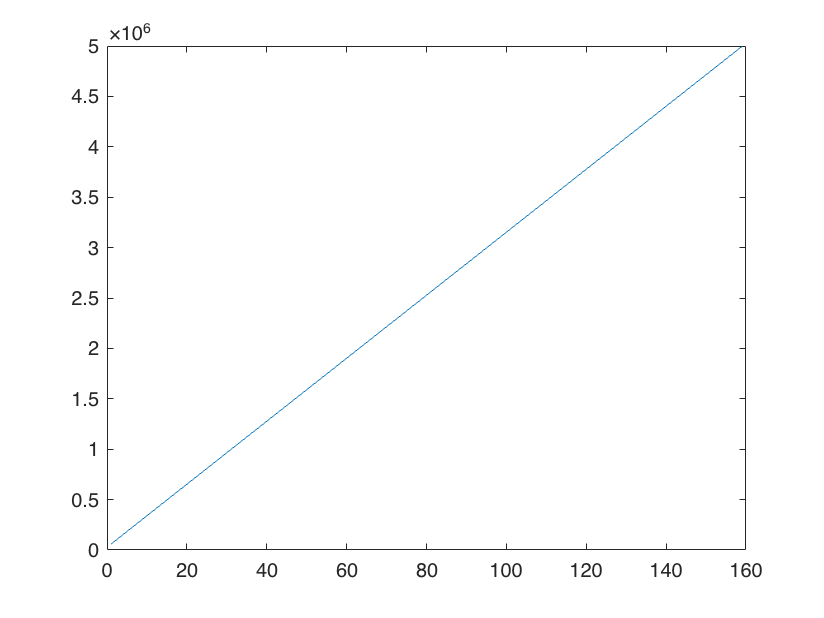

figure
plot(label_T)

## Preprocess the ECG

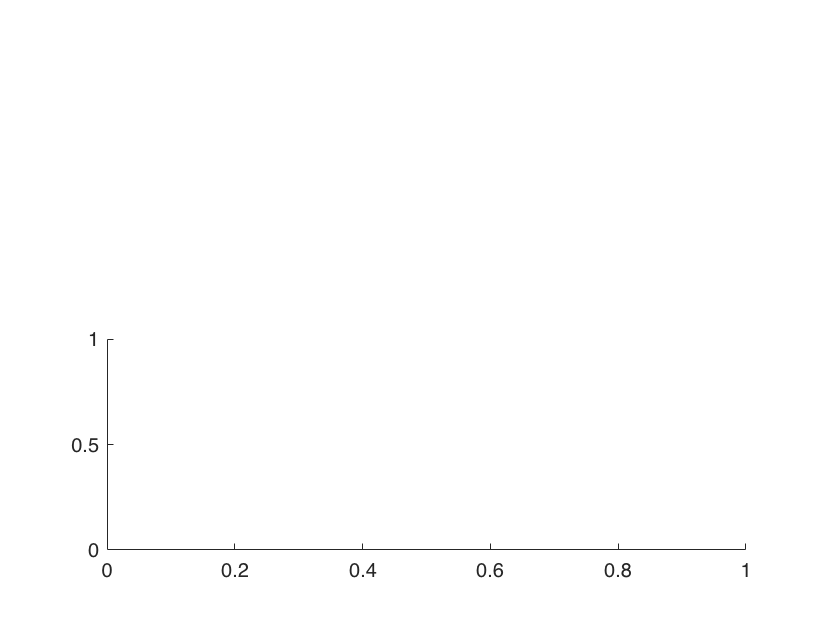

%sampling frequency is 256 Hz
Fs = 256;
Fnyq = Fs/2;
Ts = 1/Fs;
L = size(T(:,1));
%bandpass filter 0.1-250Hz
freq_low = 0.1;
freq_high = 1;
[z,p,k]=butter(3,[freq_low freq_high]/(Fs/2),'bandpass');
[sos,g]=zp2sos(z,p,k);
filt_ecg = filtfilt(sos,g,signal.ecg); 
%clean_sig = abs(sEMG_v2-mean(sEMG_v2));
figure
subplot(2, 1, 2)

plot(t, signal.ecg)

Unrecognized function or variable 't'.

title("Filtered signal");
subplot(2, 1, 1)
plot(t, filt_ecg)
title("Original Signal")

## Extract Features

let's start by extracting the mean ECG Vp-p over label interval

%starting ECG p-p for each window
f1 = []; windowed_data = [];
for x = 1:size(T)
    f1(end+1, :) = signal.ecg(T(x));
    for y = T: T+1
        windowed_data(end+1, :) = signal.ecg(y);
    end
end
f1

f1 = 	1.0e+03 *

   -2.4383
   -2.4640
   -2.3660
   -2.3857
   -2.3803
   -2.0637
   -2.3896
   -0.9154
   -2.1444
   -2.3599


windowed_data

windowed_data = 	1.0e+03 *

   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434   -2.4383   -2.4434


%Thiam et al. preprocessing approach
%4 sec shift from label onset
%fixed window length of 4.5sec
shift_time = [];
for x = 1:size(T)+4
    shift_time(end+1,:) = label_T(x) + 4;
end

Index exceeds the number of array elements. Index must not exceed 159.

shift_time

## Train Model

%load the extracted features
